path = "abr_signal2.mat";

file = load(path);

Dla każdej struktury wyznaczamy maksimum fali V i następujące po niej minimum. Następnie obliczamy V-pp, a potem stosunek V-pp do mean. W pewnym momencie stosunek będzie bardzo mały i wtedy należy stwierdzić, że fala V jest nie wykryta. Miejsce wystąpienia fali zwiększa się dla każdego kolejnego natężenia. Należy rozpocząć poszukiwanie maksimum od miejsca wystąpienia maksimum z poprzedniego natężenia.

data = file.abr_signal2

data = 10×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}



db = data{2}.dB

db = 110

signal = data{1}.data;

fp = 100000;

ones_arr = transpose(signal(length(signal)-1)*ones(1,24));
%signal =  cat(1, signal, )
signal = [signal; ones_arr]

signal =      7
     8
     7
     6
     5
     4
     2
     1
     0
     1



t = 0:1/fp:(length(signal)-1)*(1/fp);
t = t * 1000;

[swa,swd] = swt(signal,6,'bior5.5');

swa = swa(6, :)

swa =   -25.6054  -26.1373  -26.7154  -27.3374  -28.0046  -28.7129  -29.4583  -30.2412  -31.0590  -31.9045  -32.7781  -33.6817  -34.6167  -35.5904  -36.6060  -37.6638  -38.7640  -39.8974  -41.0554  -42.2314  -43.4153  -44.5967  -45.7677  -46.9190  -48.0430  -49.1385  -50.2013  -51.2253  -52.2054  -53.1341  -54.0068  -54.8204  -55.5697  -56.2509  -56.8609  -57.4000  -57.8703  -58.2755  -58.6166  -58.8952  -59.1130  -59.2670  -59.3572  -59.3831  -59.3435  -59.2385  -59.0669  -58.8278  -58.5228  -58.1578



[max, idx_max] = findpeaks(swa)

max =    80.5580  191.3335  166.9356  -40.0838  -21.4967


idx_max =          145         379         554         751        1010


[min, idx_min] = findpeaks(-swa)

min =    59.3831   43.9192  -33.9221  125.5990  129.9296


idx_min =     44   286   451   670   880



idx_V = find(idx_max > 550 & idx_max < 700)

idx_V = 3

V_max = max(idx_V)

V_max = 166.9356


idx_V_min = find(idx_min > idx_max(idx_V))

idx_V_min =      4     5


idx_V_min = idx_V_min(1)

idx_V_min = 4

V_min = swa(idx_min(idx_V_min))

V_min = -125.5990


V_pp = V_max - V_min

V_pp = 292.5346

V_mean = abs(mean(swa))

V_mean = 1.1641


sto = V_pp / V_mean

sto = 251.3049

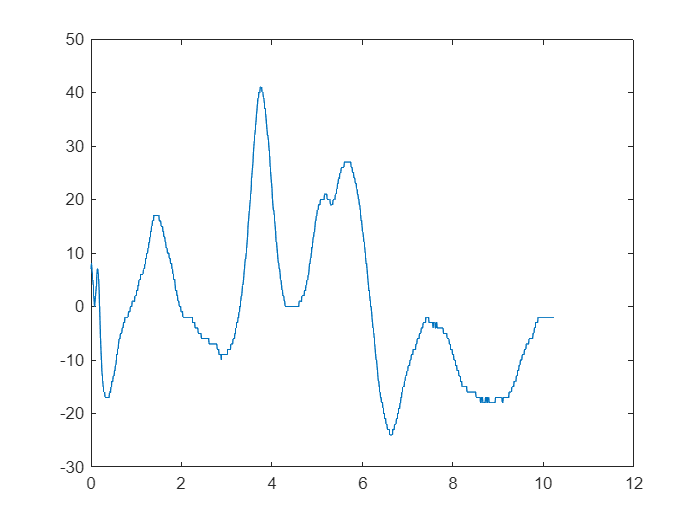

figure
plot(t, signal)

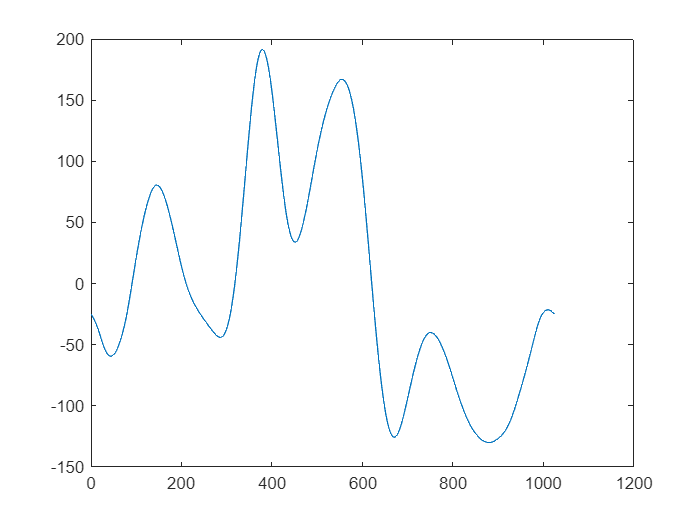

figure 
plot(swa)